# Estimate Mdl00_00

## Load the data and fit the model


% script for estimating offset to onset lag model

DataTable00 = getDataTable00('vonMises');
formula0 = [...
    'EAPchi  ~ 1 + zero + commute + noncom + learnt:noncom',...
    '+ (1 | pairId) + (1 | subjectId)'];
modelObj = fitlme(DataTable00,formula0);
disp(modelObj);


Linear mixed-effects model fit by ML

Model information:
    Number of observations            1149
    Fixed effects coefficients           5
    Random effects coefficients         68
    Covariance parameters                3

Formula:
    EAPchi ~ 1 + zero + commute + noncom + learnt:noncom + (1 | pairId) + (1 | subjectId)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    11728    11768    -5856            11712   

Fixed effects coefficients (95% CIs):
    Name                     Estimate    SE        tStat      DF      pValue        Lower      Upper  
    {'(Intercept)'  }         98.058     6.9638     14.081    1144    1.2022e-41     84.395     111.72
    {'zero'         }        -86.316     5.6065    -15.396    1144    9.4967e-49    -97.317    -75.316
    {'commute'      }         -62.19     7.2486    -8.5796    1144    3.0561e-17    -76.412    -47.968
    {'noncom'  

pVals = dataset2table(modelObj.Coefficients(:,'pValue'));
coefficient = dataset2table(modelObj.Coefficients(:,'Name'));
[h,alphas] = holmBonf(pVals{:,1});
alphas = table(alphas);
mC = [coefficient,pVals,alphas];
mC.Properties.VariableNames = {'coefficient','pVal','corrected_Alpha_Level'};
disp(mC);

       coefficient          pVal       corrected_Alpha_Level
    _________________    __________    _____________________

    {'(Intercept)'  }    1.2022e-41            0.0125       
    {'zero'         }    9.4967e-49              0.01       
    {'commute'      }    3.0561e-17          0.016667       
    {'noncom'       }    1.9538e-15             0.025       
    {'learnt:noncom'}      0.022763              0.05       




%TO DO: maybe move round order of colums in datatable if can be bothered

formula1 = [...
    'MAPchi  ~ 1 + zero + commute + noncom + learnt:noncom',...
    '+ (1 | pairId) + (1 | subjectId)'];
modelObj1= fitlme(DataTable00,formula1);
disp(modelObj1);


Linear mixed-effects model fit by ML

Model information:
    Number of observations            1149
    Fixed effects coefficients           5
    Random effects coefficients         68
    Covariance parameters                3

Formula:
    MAPchi ~ 1 + zero + commute + noncom + learnt:noncom + (1 | pairId) + (1 | subjectId)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    11715    11755    -5849.5          11699   

Fixed effects coefficients (95% CIs):
    Name                     Estimate    SE        tStat      DF      pValue        Lower      Upper  
    {'(Intercept)'  }         95.153     6.9463     13.698    1144    1.1624e-39     81.524     108.78
    {'zero'         }        -83.765     5.3073    -15.783    1144    6.3974e-51    -94.179    -73.352
    {'commute'      }        -59.887     6.8616    -8.7278    1144    9.0299e-18     -73.35    -46.424
    {'noncom'  

%pattern of effects is not different for Maximum A posterior compared to
%Expected A posterior 
% All effects survive multiple comparison adjusted alpha levels

Plot the lags of the qTypes with the offsets of Sup, in only the people that learnt?

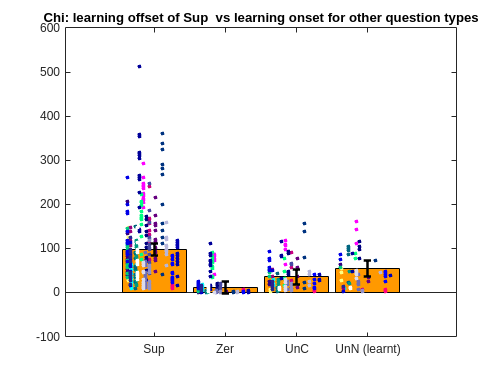

% is learn evaluated on a per question basis or on a per subject basis??
cDT = DataTable00;
%remove values for questions which weren't learnt
cDT{~(cDT.learnt==1),'EAPchi'} = nan;

pairType = {'Sup', 'Zer','UnC','UnN'};
% data series will be subjects who learnt at least one noncom question
sub = unique(DataTable00{DataTable00.learnt==1 & DataTable00.pairType =='UnN','subjectId'});
nSubs = numel(sub);
pairId = cell(nSubs,1);
Y = cell(nSubs,1);
X = cell(nSubs,1);
for iSub=1:nSubs
    scDT = cDT(cDT.subjectId == sub(iSub),:);
    cY = cell(1,4);
    cX = cell(1,4);
    for ii = 1:4
        %get the chi vals for that subject in that q Type
        s = scDT.pairType==pairType{ii};
        cY{ii} = scDT.EAPchi(s);
        cX{ii} = ones(size(cY{ii})).*ii;
    end
    
    Y{iSub} = vertcat(cY{:});
    X{iSub} = vertcat(cX{:}); %for every y point, the x coord is the current qType
end

% y var is learning off set

figure;
%sup
chi = nan(1,4);
upp = nan(1,4);
[~,chi(1),~,upp(1)] = getXEUL(modelObj,...
    1,0,0,0,0);
%zero
[~,chi(2),~,upp(2)] = getXEUL(modelObj,...
    1,1,0,0,0);
%commute
[~,chi(3),~,upp(3)] = getXEUL(modelObj,...
    1,0,1,0,0);
%noncom (learnt)
[~,chi(4),~,upp(4)] = getXEUL(modelObj,...
    1,0,0,1,1);

errors = upp - chi;
b = bar(chi,'FaceColor',[1,0.6,0]);
b.BarWidth = 0.9;
labels = cellstr(pairType);
labels{4} = 'UnN (learnt)';
set(gca, 'XTickLabel',labels);
hold on
%scatter data for learners
hues = colorcube(nSubs);
hues(:,3) = rescale(hues(:,3),0.5,1);
jitter = 0.4;
vals = linspace(0,1,nSubs);
for jj=1:nSubs
    x = X{jj};
    sign = round(rand(1));
    if ~sign
        sign = -1;
    end
    x = x + randsample(vals,1)*jitter*sign;
    scatter(x,Y{jj},10,hues(jj,:),'filled')
end 
%add error bars over the top for the means
for kk = 1:numel(pairType)
    s = cDT.pairType==pairType(kk);
    y = cDT.EAPchi(s); 
    errorbar(kk, chi(kk), errors(kk), ...
        'k', 'linestyle', 'none', 'LineWidth', 2);
end
title('Chi: learning offset of Sup  vs learning onset for other question types')
hold off;

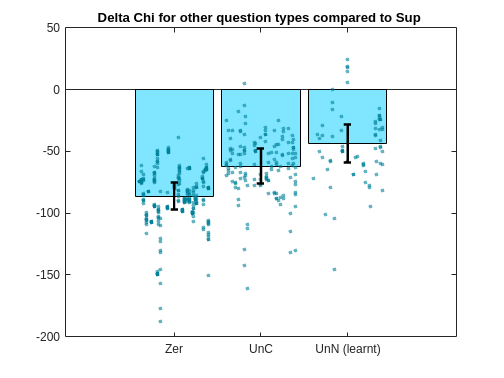

% Bar graph plotting the lag estimates for each question type,and individual
% data which is the data for each person's chi for each pair - (the
% estimated group sup chi + subject intercept)
% is learn evaluated on a per question basis or on a per subject basis??
% data series will be subjects who learnt at least one noncom question
subs = unique(DataTable00.subjectId);
nSubs = numel(subs);
cDT = DataTable00;
%remove values for questions which weren't learnt
cDT{~(cDT.learnt==1),'EAPchi'} = nan;

%get sup chi estimate for the group 
[~,supChi] = getXEUL(modelObj,...
    1,0,0,0,0);
upp = [];
%zero
[~,estLag(1),~,upp(1)] = getXEUL(modelObj,...
    0,1,0,0,0);
%commute
[~,estLag(2),~,upp(2)] = getXEUL(modelObj,...
    0,0,1,0,0);
%noncom (learnt)
[~,estLag(3),~,upp(3)] = getXEUL(modelObj,...
    0,0,0,1,1);


% TO MAKE NEW COLOUMN OF TABLE WHERE YOU HAVE PAIR ID LEVEL DIFF FROM SUP
% CHI
%EXTRACT RANDOM EFFECT FOR PERSON, ADD THAT TO SUP ESTIMATES AND REMOVE
%FROM PAIR ID CHI

[~,~,Rfx] = randomEffects(modelObj);

Rfx = dataset2table(Rfx);

%Data points bit:
for iSub=1:nSubs
    cSubId = subs(iSub);
    scDT = cDT(cDT.subjectId == cSubId,:);
    %get the chi vals for that subject in that q Type
    subIntcpt = Rfx.Estimate(strcmp(Rfx.Level,cellstr(cSubId)));
    scDT.lag = scDT.EAPchi - (supChi + subIntcpt);
    if iSub==1
        newT = scDT;
    else
        newT = [newT;scDT];%#ok<AGROW
    end
end
pairType = {'Sup','Zer','UnC','UnN'};
newT{newT.pairType=='Sup','lag'} = nan;
%draw main bar graph
errors = upp - estLag;
figure;
b = bar(estLag,'FaceColor',[0.5,0.9,1]);
b.BarWidth = 0.9;
labels = pairType(2:end);
labels{3} = 'UnN (learnt)';
set(gca, 'XTickLabel',labels);
hold on;

newT.xCoord = cell2mat(arrayfun(@(x) find(pairType == x),...
    newT.pairType, 'UniformOutput',false));
newT.xCoord = newT.xCoord -1;

%draw datapoints for each person and pairId for their lag from model
%estimated sup chi
jitter = 0.4;
vals = linspace(0,1,nSubs);
for jj=1:nSubs
    cSubId = subs(jj);
    sign = round(rand(1));
    if ~sign
        sign = -1;
    end
    x = newT{newT.subjectId==cSubId,'xCoord'};
    x = x + randsample(vals,1)*jitter*sign;
    y = newT{newT.subjectId==cSubId,'lag'};
    scatter(x,y,10,'filled','MarkerFaceColor',[0,0.5,0.6],'MarkerFaceAlpha',0.6)
end 
pairType = pairType(2:end);
%draw error bars
for kk = 1:numel(pairType)
    s = cDT.pairType==pairType(kk);
    y = cDT.EAPchi(s); 
    errorbar(kk, estLag(kk), errors(kk), ...
        'k', 'linestyle', 'none', 'LineWidth', 2);
end
title('Delta Chi for other question types compared to Sup ')